clear;
close all;
clc;

# **PREPROCESSING**

**MEMBACA CITRA AWAL**

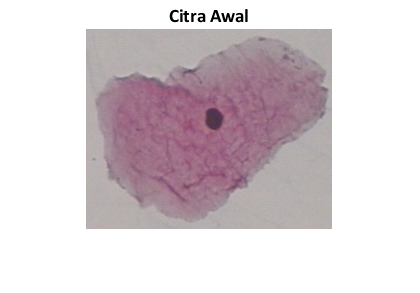

% I = imread('Abnormal/148494967-148494986-001.BMP');
I = imread('Normal\157223735-157223766-001.BMP');
I = imresize(I, [200 NaN]);
figure, imshow(I), title('Citra Awal', 'FontName','Calibri','FontSize',14,'FontWeight','bold');

- Membaca citra sel nukleus normal/abnormal (**.bmp**)

- Mengatur ukuran citra menjadi 200 NaN (mempertahankan aspek rasio dari citra)

**MEMPERBAIKI KONTRAS CITRA AWAL**

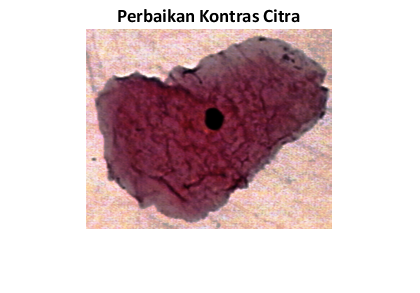

H = histeq(I);
M = imgaussfilt3(H);
imshow(M), title('Perbaikan Kontras Citra', 'FontName','Calibri','FontSize',14,'FontWeight','bold')

- Memperbaiki kontras citra dengan histogram equalization

- Mengaplikasikan filter gaussian pada citra

# **SEGMENTASI K-MEANS CLUSTERING**

**Konversi Citra ke Ruang Warna LAB**

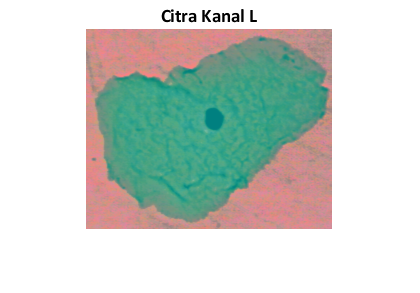

cform = makecform('srgb2lab');
lab_M = applycform(M,cform);
imshow (lab_M), title('Citra Kanal L', 'FontName','Calibri','FontSize',14,'FontWeight','bold')

**Konversi ke Kanal a*b***

ab_smear = double(lab_M(:,:,2:3));
smear_rows = size(ab_smear, 1);
smear_cols = size(ab_smear, 2);
ab_smear = reshape(ab_smear,smear_rows*smear_cols, 2);

Klasifikasikan citra ke dalam ruang warna a*b*, dimana hanya kanal a & b yang memiliki dimensi warna pada ruang warna LAB

**Klasifikasi K-Means**

nColorsSmear = 3;
[cluster_idx, cluster_center] = kmeans(ab_smear, nColorsSmear, 'distance', 'sqEuclidean', 'Replicates', 3);
pixel_labels = reshape(cluster_idx, smear_rows, smear_cols);

- Klasifikasi dgn metode K-Means dilakukan sebanyak 3x (3 warna)

- Euclidean distance digunakan sebagai pengukur jarak dari masing-masing pusat cluster

- Pada masing2 cluster yang akan dicari adalah objek nukleus dari  citra pap smear

**Membuat Array untuk Citra Hasil Segmentasi**

segmented_images = cell(1,3);
rgb_label = repmat(pixel_labels,[1,1,3]);

membuat 3 cell array yg akan digunakan untuk menyimpan hasil clustering

**Menempatkan Hasil Segmentasi ke dalam Array**

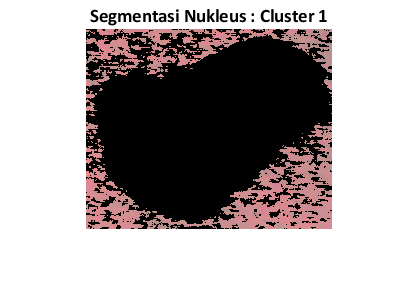

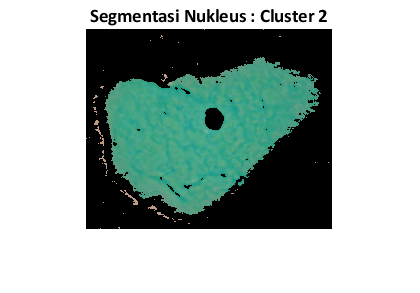

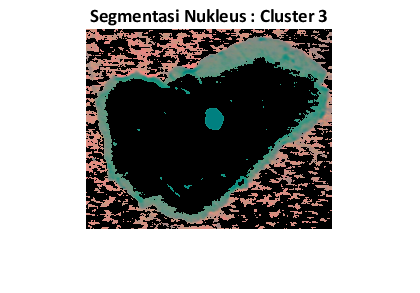

for k = 1:nColorsSmear
    colors = lab_M; %I;
    colors(rgb_label ~= k) = 0;
    segmented_images{k} = colors;
    figure, imshow(segmented_images{k});title(['Segmentasi Nukleus : Cluster ', num2str(k)], 'FontName','Calibri','FontSize',14,'FontWeight','bold');
end

membuat perulangan sebanyak n kali jumlah cluster yang ditentukan

**Perankingan Cluster**

%% Segmentasi Nukleus ke dalam objek yang terpisah
nilai_rata_cluster = mean(cluster_center,2);
[tmp, idx] = sort(nilai_rata_cluster);
cluster_smear = idx(1);

Perankingan cluster dilakukan dengan cara mencari rata-rata pusat cluster dan melakukan sorting cluster sesuai dengan rata-rata tersebut, sehingga urutan cluster yang ditampilkan tidak akan berubah-ubah

**Masking**

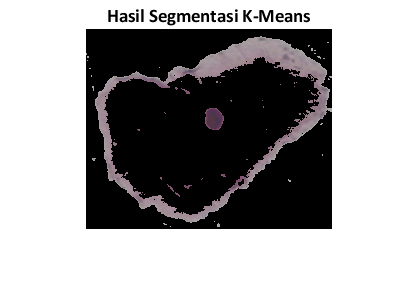

L = M(:,:,1);
smear_idx = find(pixel_labels == cluster_smear);
L_smear = L(smear_idx);
segment_smear = imbinarize(L_smear);

smear_labels = repmat(uint8(0),[smear_rows smear_cols]);
smear_labels(smear_idx(segment_smear==false)) = 1;
smear_labels = repmat(smear_labels,[1 1 3]);
nukleus_smear = I;
nukleus_smear(smear_labels ~= 1) = 0;
figure, imshow(nukleus_smear), title('Hasil Segmentasi K-Means', 'FontName','Calibri','FontSize',14,'FontWeight','bold');

Masking disini bertujuan untuk membedakan antara sel nukleus dan juga background dari citra pap smear, sehingga dilakukan segmentasi dengan ciri warna yang berbeda

# **POST PROCESSING**

**Post-processing dengan Operasi Morphology**

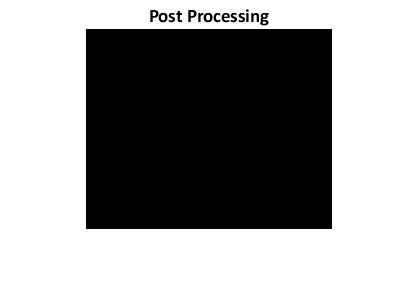

BW = rgb2gray(nukleus_smear);
BW = im2bw(BW, graythresh(BW));
BW = imfill(BW, 'holes');
BW = imclearborder(BW);
BW = bwmorph(BW,'erode',1);
BW = bwareaopen(BW, 100);
imshow(BW), title('Post Processing', 'FontName','Calibri','FontSize',14,'FontWeight','bold')

Mengubah citra hasil segmentasi K Means bertujuan untuk mempermudah dalam mengaplikasikan operasi untuk menghilangkan noise pada citra, sehingga hasil akhir nya berupa citra nukleus/inti sel dari sel pap smear

**Labelling Citra**

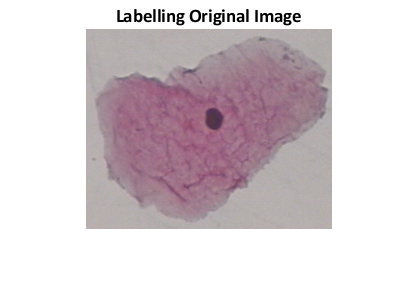

BWoutline = bwperim(BW);
label_smear = I;
label_smear(BWoutline ~= 0) = 255;
imshow(label_smear), title('Labelling Original Image', 'FontName','Calibri','FontSize',14,'FontWeight','bold')

Melabelkan citra asli dengan garis pinggir berdasarkan hasil segmentasi

# **EKSTRAKSI FITUR & KLASIFIKASI DECISION TREE**

[B,L] = bwboundaries(BW,'noholes');
stats = regionprops(L,'BoundingBox','Centroid','Area','Perimeter','Eccentricity');
hold on ;


[m,n] = size(I);
for k=1:length(B)
    boundary = B{k};
    Area = (stats(k).Area)/(m*n)
    Perimeter = (stats(k).Perimeter)/(2*(m+n))
    Eccentricity = stats(k).Eccentricity
    
%     if Area < 500
%         fprintf('\n')
%         fprintf('Sel Nukleus ke %d merupakan Citra Sel Normal dengan \nArea = %d,\nPerimeter = %d \nEccentricity = %d', k, Area, Perimeter, Eccentricity)
%         text(boundary(2,2)+10,boundary(1,1),'Normal','Color','g','FontWeight','bold');
%     elseif Perimeter >= 100
%         if Eccentricity > 0.5
%             fprintf('Sel Nukleus ke %d merupakan Citra Sel Abnormal dengan \nArea = %d\nPerimeter = %d \nEccentricity = %d', k, Area, Perimeter, Eccentricity)
%             text(boundary(2,2)+10,boundary(1,1),'Abnormal','Color','g','FontWeight','bold');
%         end
%     end
end

- Ekstraksi fitur menggunakan regionprops, dengan mengekstrak ciri perimeter, area dan eccentricity.

- Klasifikasi menggunakan metode decision tree